# **Parameter Recoverability **

# **FLUX WORKHOP SECTION D **

We will simulate the data from a model with 1 learning rate and a range of values for softmax temperature. 

We will next fit these simulated data and compared "true" (e.g. simulated generative values) and recovered values for both softmax and learning rate. 

In a similar way you can vary learning rates while keeping softmax temperature fixed and check the recoverability for the learning rate. 

% Script to simulate RL Rescorla Wagner model with different sets of paramaters
% Fit the simulated data
% Plot the true vs. recovered parameters
% Vasilisa Skvortsova, 08/2021 for FLUX

clear all; 
close all; 
clc; 

### PART 1. SIMULATE THE DATA 

Simulate N = 30 subjects who will play a 2-arm binary reward learning task with p(reward) = 0.8 and no reversals. It means the rewarding bandit stays the same throughout the session. The difference between fitting and simulation is that when you simulate the data you use a choice emission function  to produce subject's choices while in fitting you use actual choices that you have collected from your participants. 


cfg_sim.nsub      = 30;
cfg_sim.p         = 0.8; % 80/20 
cfg_sim.nblck     = 1; % assuming 1 block 
cfg_sim.alphach   = 0.5; % learning rate for the chosen option
cfg_sim.alphauch  = 0; 
cfg_sim.ntrl      = 100; % try to vary the number of trials to see how it will affect the recovery


sim_param  = linspace(0.1,1,20); % linearly spaced values for the softmax 

cfg_sim.paramname = 'tau'; 
for idx = 1:numel(sim_param)
    fprintf('Simulating tau = %0.2f\n',sim_param(idx))
    cfg_sim.tau  = sim_param(idx);
    sim_out  = simulate_data(cfg_sim);
    sim_data.(sprintf('tau%d',idx)) = sim_out; 
end

Simulating tau = 0.10


Simulating subject 1
Simulating subject 2
Simulating subject 3
Simulating subject 4
Simulating subject 5
Simulating subject 6
Simulating subject 7
Simulating subject 8
Simulating subject 9
Simulating subject 10
Simulating subject 11
Simulating subject 12
Simulating subject 13
Simulating subject 14
Simulating subject 15
Simulating subject 16
Simulating subject 17
Simulating subject 18
Simulating subject 19
Simulating subject 20
Simulating subject 21
Simulating subject 22
Simulating subject 23
Simulating subject 24
Simulating subject 25
Simulating subject 26
Simulating subject 27
Simulating subject 28
Simulating subject 29
Simulating subject 30


Simulating tau = 0.15


Simulating subject 1
Simulating subject 2
Simulating subject 3
Simulating subject 4
Simulating subject 5
Simulating subject 6
Simulating subject 7
Simulating subject 8
Simulating subject 9
Simulating subject 10
Simulating subject 11
Simulating subject 12
Simulating subject 13
Simulating subject 14
Simulating subject 15
Simulating subject 16
Simulating subject 17
Simulating subject 18
Simulating subject 19
Simulating subject 20
Simulating subject 21
Simulating subject 22
Simulating subject 23
Simulating subject 24
Simulating subject 25
Simulating subject 26
Simulating subject 27
Simulating subject 28
Simulating subject 29
Simulating subject 30


Simulating tau = 0.19


Simulating subject 1
Simulating subject 2
Simulating subject 3
Simulating subject 4
Simulating subject 5
Simulating subject 6
Simulating subject 7
Simulating subject 8
Simulating subject 9
Simulating subject 10
Simulating subject 11
Simulating subject 12
Simulating subject 13
Simulating subject 14
Simulating subject 15
Simulating subject 16
Simulating subject 17
Simulating subject 18
Simulating subject 19
Simulating subject 20
Simulating subject 21
Simulating subject 22
Simulating subject 23
Simulating subject 24
Simulating subject 25
Simulating subject 26
Simulating subject 27
Simulating subject 28
Simulating subject 29
Simulating subject 30


Simulating tau = 0.24


Simulating subject 1
Simulating subject 2
Simulating subject 3
Simulating subject 4
Simulating subject 5
Simulating subject 6
Simulating subject 7
Simulating subject 8
Simulating subject 9
Simulating subject 10
Simulating subject 11
Simulating subject 12
Simulating subject 13
Simulating subject 14
Simulating subject 15
Simulating subject 16
Simulating subject 17
Simulating subject 18
Simulating subject 19
Simulating subject 20
Simulating subject 21
Simulating subject 22
Simulating subject 23
Simulating subject 24
Simulating subject 25
Simulating subject 26
Simulating subject 27
Simulating subject 28
Simulating subject 29
Simulating subject 30


Simulating tau = 0.29


Simulating subject 1
Simulating subject 2
Simulating subject 3
Simulating subject 4
Simulating subject 5
Simulating subject 6
Simulating subject 7
Simulating subject 8
Simulating subject 9
Simulating subject 10
Simulating subject 11
Simulating subject 12
Simulating subject 13
Simulating subject 14
Simulating subject 15
Simulating subject 16
Simulating subject 17
Simulating subject 18
Simulating subject 19
Simulating subject 20
Simulating subject 21
Simulating subject 22
Simulating subject 23
Simulating subject 24
Simulating subject 25
Simulating subject 26
Simulating subject 27
Simulating subject 28
Simulating subject 29
Simulating subject 30


Simulating tau = 0.34


Simulating subject 1
Simulating subject 2
Simulating subject 3
Simulating subject 4
Simulating subject 5
Simulating subject 6
Simulating subject 7
Simulating subject 8
Simulating subject 9
Simulating subject 10
Simulating subject 11
Simulating subject 12
Simulating subject 13
Simulating subject 14
Simulating subject 15
Simulating subject 16
Simulating subject 17
Simulating subject 18
Simulating subject 19
Simulating subject 20
Simulating subject 21
Simulating subject 22
Simulating subject 23
Simulating subject 24
Simulating subject 25
Simulating subject 26
Simulating subject 27
Simulating subject 28
Simulating subject 29
Simulating subject 30


Simulating tau = 0.38


Simulating subject 1
Simulating subject 2
Simulating subject 3
Simulating subject 4
Simulating subject 5
Simulating subject 6
Simulating subject 7
Simulating subject 8
Simulating subject 9
Simulating subject 10
Simulating subject 11
Simulating subject 12
Simulating subject 13
Simulating subject 14
Simulating subject 15
Simulating subject 16
Simulating subject 17
Simulating subject 18
Simulating subject 19
Simulating subject 20
Simulating subject 21
Simulating subject 22
Simulating subject 23
Simulating subject 24
Simulating subject 25
Simulating subject 26
Simulating subject 27
Simulating subject 28
Simulating subject 29
Simulating subject 30


Simulating tau = 0.43


Simulating subject 1
Simulating subject 2
Simulating subject 3
Simulating subject 4
Simulating subject 5
Simulating subject 6
Simulating subject 7
Simulating subject 8
Simulating subject 9
Simulating subject 10
Simulating subject 11
Simulating subject 12
Simulating subject 13
Simulating subject 14
Simulating subject 15
Simulating subject 16
Simulating subject 17
Simulating subject 18
Simulating subject 19
Simulating subject 20
Simulating subject 21
Simulating subject 22
Simulating subject 23
Simulating subject 24
Simulating subject 25
Simulating subject 26
Simulating subject 27
Simulating subject 28
Simulating subject 29
Simulating subject 30


Simulating tau = 0.48


Simulating subject 1
Simulating subject 2
Simulating subject 3
Simulating subject 4
Simulating subject 5
Simulating subject 6
Simulating subject 7
Simulating subject 8
Simulating subject 9
Simulating subject 10
Simulating subject 11
Simulating subject 12
Simulating subject 13
Simulating subject 14
Simulating subject 15
Simulating subject 16
Simulating subject 17
Simulating subject 18
Simulating subject 19
Simulating subject 20
Simulating subject 21
Simulating subject 22
Simulating subject 23
Simulating subject 24
Simulating subject 25
Simulating subject 26
Simulating subject 27
Simulating subject 28
Simulating subject 29
Simulating subject 30


Simulating tau = 0.53


Simulating subject 1
Simulating subject 2
Simulating subject 3
Simulating subject 4
Simulating subject 5
Simulating subject 6
Simulating subject 7
Simulating subject 8
Simulating subject 9
Simulating subject 10
Simulating subject 11
Simulating subject 12
Simulating subject 13
Simulating subject 14
Simulating subject 15
Simulating subject 16
Simulating subject 17
Simulating subject 18
Simulating subject 19
Simulating subject 20
Simulating subject 21
Simulating subject 22
Simulating subject 23
Simulating subject 24
Simulating subject 25
Simulating subject 26
Simulating subject 27
Simulating subject 28
Simulating subject 29
Simulating subject 30


Simulating tau = 0.57


Simulating subject 1
Simulating subject 2
Simulating subject 3
Simulating subject 4
Simulating subject 5
Simulating subject 6
Simulating subject 7
Simulating subject 8
Simulating subject 9
Simulating subject 10
Simulating subject 11
Simulating subject 12
Simulating subject 13
Simulating subject 14
Simulating subject 15
Simulating subject 16
Simulating subject 17
Simulating subject 18
Simulating subject 19
Simulating subject 20
Simulating subject 21
Simulating subject 22
Simulating subject 23
Simulating subject 24
Simulating subject 25
Simulating subject 26
Simulating subject 27
Simulating subject 28
Simulating subject 29
Simulating subject 30


Simulating tau = 0.62


Simulating subject 1
Simulating subject 2
Simulating subject 3
Simulating subject 4
Simulating subject 5
Simulating subject 6
Simulating subject 7
Simulating subject 8
Simulating subject 9
Simulating subject 10
Simulating subject 11
Simulating subject 12
Simulating subject 13
Simulating subject 14
Simulating subject 15
Simulating subject 16
Simulating subject 17
Simulating subject 18
Simulating subject 19
Simulating subject 20
Simulating subject 21
Simulating subject 22
Simulating subject 23
Simulating subject 24
Simulating subject 25
Simulating subject 26
Simulating subject 27
Simulating subject 28
Simulating subject 29
Simulating subject 30


Simulating tau = 0.67


Simulating subject 1
Simulating subject 2
Simulating subject 3
Simulating subject 4
Simulating subject 5
Simulating subject 6
Simulating subject 7
Simulating subject 8
Simulating subject 9
Simulating subject 10
Simulating subject 11
Simulating subject 12
Simulating subject 13
Simulating subject 14
Simulating subject 15
Simulating subject 16
Simulating subject 17
Simulating subject 18
Simulating subject 19
Simulating subject 20
Simulating subject 21
Simulating subject 22
Simulating subject 23
Simulating subject 24
Simulating subject 25
Simulating subject 26
Simulating subject 27
Simulating subject 28
Simulating subject 29
Simulating subject 30


Simulating tau = 0.72


Simulating subject 1
Simulating subject 2
Simulating subject 3
Simulating subject 4
Simulating subject 5
Simulating subject 6
Simulating subject 7
Simulating subject 8
Simulating subject 9
Simulating subject 10
Simulating subject 11
Simulating subject 12
Simulating subject 13
Simulating subject 14
Simulating subject 15
Simulating subject 16
Simulating subject 17
Simulating subject 18
Simulating subject 19
Simulating subject 20
Simulating subject 21
Simulating subject 22
Simulating subject 23
Simulating subject 24
Simulating subject 25
Simulating subject 26
Simulating subject 27
Simulating subject 28
Simulating subject 29
Simulating subject 30


Simulating tau = 0.76


Simulating subject 1
Simulating subject 2
Simulating subject 3
Simulating subject 4
Simulating subject 5
Simulating subject 6
Simulating subject 7
Simulating subject 8
Simulating subject 9
Simulating subject 10
Simulating subject 11
Simulating subject 12
Simulating subject 13
Simulating subject 14
Simulating subject 15
Simulating subject 16
Simulating subject 17
Simulating subject 18
Simulating subject 19
Simulating subject 20
Simulating subject 21
Simulating subject 22
Simulating subject 23
Simulating subject 24
Simulating subject 25
Simulating subject 26
Simulating subject 27
Simulating subject 28
Simulating subject 29
Simulating subject 30


Simulating tau = 0.81


Simulating subject 1
Simulating subject 2
Simulating subject 3
Simulating subject 4
Simulating subject 5
Simulating subject 6
Simulating subject 7
Simulating subject 8
Simulating subject 9
Simulating subject 10
Simulating subject 11
Simulating subject 12
Simulating subject 13
Simulating subject 14
Simulating subject 15
Simulating subject 16
Simulating subject 17
Simulating subject 18
Simulating subject 19
Simulating subject 20
Simulating subject 21
Simulating subject 22
Simulating subject 23
Simulating subject 24
Simulating subject 25
Simulating subject 26
Simulating subject 27
Simulating subject 28
Simulating subject 29
Simulating subject 30


Simulating tau = 0.86


Simulating subject 1
Simulating subject 2
Simulating subject 3
Simulating subject 4
Simulating subject 5
Simulating subject 6
Simulating subject 7
Simulating subject 8
Simulating subject 9
Simulating subject 10
Simulating subject 11
Simulating subject 12
Simulating subject 13
Simulating subject 14
Simulating subject 15
Simulating subject 16
Simulating subject 17
Simulating subject 18
Simulating subject 19
Simulating subject 20
Simulating subject 21
Simulating subject 22
Simulating subject 23
Simulating subject 24
Simulating subject 25
Simulating subject 26
Simulating subject 27
Simulating subject 28
Simulating subject 29
Simulating subject 30


Simulating tau = 0.91


Simulating subject 1
Simulating subject 2
Simulating subject 3
Simulating subject 4
Simulating subject 5
Simulating subject 6
Simulating subject 7
Simulating subject 8
Simulating subject 9
Simulating subject 10
Simulating subject 11
Simulating subject 12
Simulating subject 13
Simulating subject 14
Simulating subject 15
Simulating subject 16
Simulating subject 17
Simulating subject 18
Simulating subject 19
Simulating subject 20
Simulating subject 21
Simulating subject 22
Simulating subject 23
Simulating subject 24
Simulating subject 25
Simulating subject 26
Simulating subject 27
Simulating subject 28
Simulating subject 29
Simulating subject 30


Simulating tau = 0.95


Simulating subject 1
Simulating subject 2
Simulating subject 3
Simulating subject 4
Simulating subject 5
Simulating subject 6
Simulating subject 7
Simulating subject 8
Simulating subject 9
Simulating subject 10
Simulating subject 11
Simulating subject 12
Simulating subject 13
Simulating subject 14
Simulating subject 15
Simulating subject 16
Simulating subject 17
Simulating subject 18
Simulating subject 19
Simulating subject 20
Simulating subject 21
Simulating subject 22
Simulating subject 23
Simulating subject 24
Simulating subject 25
Simulating subject 26
Simulating subject 27
Simulating subject 28
Simulating subject 29
Simulating subject 30


Simulating tau = 1.00


Simulating subject 1
Simulating subject 2
Simulating subject 3
Simulating subject 4
Simulating subject 5
Simulating subject 6
Simulating subject 7
Simulating subject 8
Simulating subject 9
Simulating subject 10
Simulating subject 11
Simulating subject 12
Simulating subject 13
Simulating subject 14
Simulating subject 15
Simulating subject 16
Simulating subject 17
Simulating subject 18
Simulating subject 19
Simulating subject 20
Simulating subject 21
Simulating subject 22
Simulating subject 23
Simulating subject 24
Simulating subject 25
Simulating subject 26
Simulating subject 27
Simulating subject 28
Simulating subject 29
Simulating subject 30


### PART 2 FIT simulated data

We now fit the simulated choices using the same model. 

clc; 

cfg_fit.nsub      = cfg_sim.nsub;
cfg_fit.alphauch  = 0; % learning rate unchosen is fixed = not fitted 
fit_data = []; 
cfg_fit.nparams  = 3; 
for idx = 1:numel(sim_param)
     fprintf('Recovery for tau = %0.2f\n',sim_param(idx))
     
     
    params = nan(cfg_fit.nsub,cfg_fit.nparams); 
     
    for i_s = 1:cfg_fit.nsub
        
        fprintf('Fitting subject %d\n',i_s)
        cfg_fit.resp    = sim_data.(sprintf('tau%d',idx))(i_s).resp; 
        cfg_fit.rewards = sim_data.(sprintf('tau%d',idx))(i_s).rewards; 
        
        [out_fit] = fit_mle(cfg_fit); 
        params(i_s,:) = cat(2,out_fit.alphach,out_fit.alphauch,out_fit.tau); 
    end
    
    fit_data = cat(1,fit_data,cat(2,mean(params,1),std(params,1)./sqrt(cfg_fit.nsub))); 
end

Recovery for tau = 0.10


Fitting subject 1
Fitting subject 2
Fitting subject 3
Fitting subject 4
Fitting subject 5
Fitting subject 6
Fitting subject 7
Fitting subject 8
Fitting subject 9
Fitting subject 10
Fitting subject 11
Fitting subject 12
Fitting subject 13
Fitting subject 14
Fitting subject 15
Fitting subject 16
Fitting subject 17
Fitting subject 18
Fitting subject 19
Fitting subject 20
Fitting subject 21
Fitting subject 22
Fitting subject 23
Fitting subject 24
Fitting subject 25
Fitting subject 26
Fitting subject 27
Fitting subject 28
Fitting subject 29
Fitting subject 30


Recovery for tau = 0.15


Fitting subject 1
Fitting subject 2
Fitting subject 3
Fitting subject 4
Fitting subject 5
Fitting subject 6
Fitting subject 7
Fitting subject 8
Fitting subject 9
Fitting subject 10
Fitting subject 11
Fitting subject 12
Fitting subject 13
Fitting subject 14
Fitting subject 15
Fitting subject 16
Fitting subject 17
Fitting subject 18
Fitting subject 19
Fitting subject 20
Fitting subject 21
Fitting subject 22
Fitting subject 23
Fitting subject 24
Fitting subject 25
Fitting subject 26
Fitting subject 27
Fitting subject 28
Fitting subject 29
Fitting subject 30


Recovery for tau = 0.19


Fitting subject 1
Fitting subject 2
Fitting subject 3
Fitting subject 4
Fitting subject 5
Fitting subject 6
Fitting subject 7
Fitting subject 8
Fitting subject 9
Fitting subject 10
Fitting subject 11
Fitting subject 12
Fitting subject 13
Fitting subject 14
Fitting subject 15
Fitting subject 16
Fitting subject 17
Fitting subject 18
Fitting subject 19
Fitting subject 20
Fitting subject 21
Fitting subject 22
Fitting subject 23
Fitting subject 24
Fitting subject 25
Fitting subject 26
Fitting subject 27
Fitting subject 28
Fitting subject 29
Fitting subject 30


Recovery for tau = 0.24


Fitting subject 1
Fitting subject 2
Fitting subject 3
Fitting subject 4
Fitting subject 5
Fitting subject 6
Fitting subject 7
Fitting subject 8
Fitting subject 9
Fitting subject 10
Fitting subject 11
Fitting subject 12
Fitting subject 13
Fitting subject 14
Fitting subject 15
Fitting subject 16
Fitting subject 17
Fitting subject 18
Fitting subject 19
Fitting subject 20
Fitting subject 21
Fitting subject 22
Fitting subject 23
Fitting subject 24
Fitting subject 25
Fitting subject 26
Fitting subject 27
Fitting subject 28
Fitting subject 29
Fitting subject 30


Recovery for tau = 0.29


Fitting subject 1
Fitting subject 2
Fitting subject 3
Fitting subject 4
Fitting subject 5
Fitting subject 6
Fitting subject 7
Fitting subject 8
Fitting subject 9
Fitting subject 10
Fitting subject 11
Fitting subject 12
Fitting subject 13
Fitting subject 14
Fitting subject 15
Fitting subject 16
Fitting subject 17
Fitting subject 18
Fitting subject 19
Fitting subject 20
Fitting subject 21
Fitting subject 22
Fitting subject 23
Fitting subject 24
Fitting subject 25
Fitting subject 26
Fitting subject 27
Fitting subject 28
Fitting subject 29
Fitting subject 30


Recovery for tau = 0.34


Fitting subject 1
Fitting subject 2
Fitting subject 3
Fitting subject 4
Fitting subject 5
Fitting subject 6
Fitting subject 7
Fitting subject 8
Fitting subject 9
Fitting subject 10
Fitting subject 11
Fitting subject 12
Fitting subject 13
Fitting subject 14
Fitting subject 15
Fitting subject 16
Fitting subject 17
Fitting subject 18
Fitting subject 19
Fitting subject 20
Fitting subject 21
Fitting subject 22
Fitting subject 23
Fitting subject 24
Fitting subject 25
Fitting subject 26
Fitting subject 27
Fitting subject 28
Fitting subject 29
Fitting subject 30


Recovery for tau = 0.38


Fitting subject 1
Fitting subject 2
Fitting subject 3
Fitting subject 4
Fitting subject 5
Fitting subject 6
Fitting subject 7
Fitting subject 8
Fitting subject 9
Fitting subject 10
Fitting subject 11
Fitting subject 12
Fitting subject 13
Fitting subject 14
Fitting subject 15
Fitting subject 16
Fitting subject 17
Fitting subject 18
Fitting subject 19
Fitting subject 20
Fitting subject 21
Fitting subject 22
Fitting subject 23
Fitting subject 24
Fitting subject 25
Fitting subject 26
Fitting subject 27
Fitting subject 28
Fitting subject 29
Fitting subject 30


Recovery for tau = 0.43


Fitting subject 1
Fitting subject 2
Fitting subject 3
Fitting subject 4
Fitting subject 5
Fitting subject 6
Fitting subject 7
Fitting subject 8
Fitting subject 9
Fitting subject 10
Fitting subject 11
Fitting subject 12
Fitting subject 13
Fitting subject 14
Fitting subject 15
Fitting subject 16
Fitting subject 17
Fitting subject 18
Fitting subject 19
Fitting subject 20
Fitting subject 21
Fitting subject 22
Fitting subject 23
Fitting subject 24
Fitting subject 25
Fitting subject 26
Fitting subject 27
Fitting subject 28
Fitting subject 29
Fitting subject 30


Recovery for tau = 0.48


Fitting subject 1
Fitting subject 2
Fitting subject 3
Fitting subject 4
Fitting subject 5
Fitting subject 6
Fitting subject 7
Fitting subject 8
Fitting subject 9
Fitting subject 10
Fitting subject 11
Fitting subject 12
Fitting subject 13
Fitting subject 14
Fitting subject 15
Fitting subject 16
Fitting subject 17
Fitting subject 18
Fitting subject 19
Fitting subject 20
Fitting subject 21
Fitting subject 22
Fitting subject 23
Fitting subject 24
Fitting subject 25
Fitting subject 26
Fitting subject 27
Fitting subject 28
Fitting subject 29
Fitting subject 30


Recovery for tau = 0.53


Fitting subject 1
Fitting subject 2
Fitting subject 3
Fitting subject 4
Fitting subject 5
Fitting subject 6
Fitting subject 7
Fitting subject 8
Fitting subject 9
Fitting subject 10
Fitting subject 11
Fitting subject 12
Fitting subject 13
Fitting subject 14
Fitting subject 15
Fitting subject 16
Fitting subject 17
Fitting subject 18
Fitting subject 19
Fitting subject 20
Fitting subject 21
Fitting subject 22
Fitting subject 23
Fitting subject 24
Fitting subject 25
Fitting subject 26
Fitting subject 27
Fitting subject 28
Fitting subject 29
Fitting subject 30


Recovery for tau = 0.57


Fitting subject 1
Fitting subject 2
Fitting subject 3
Fitting subject 4
Fitting subject 5
Fitting subject 6
Fitting subject 7
Fitting subject 8
Fitting subject 9
Fitting subject 10
Fitting subject 11
Fitting subject 12
Fitting subject 13
Fitting subject 14
Fitting subject 15
Fitting subject 16
Fitting subject 17
Fitting subject 18
Fitting subject 19
Fitting subject 20
Fitting subject 21
Fitting subject 22
Fitting subject 23
Fitting subject 24
Fitting subject 25
Fitting subject 26
Fitting subject 27
Fitting subject 28
Fitting subject 29
Fitting subject 30


Recovery for tau = 0.62


Fitting subject 1
Fitting subject 2
Fitting subject 3
Fitting subject 4
Fitting subject 5
Fitting subject 6
Fitting subject 7
Fitting subject 8
Fitting subject 9
Fitting subject 10
Fitting subject 11
Fitting subject 12
Fitting subject 13
Fitting subject 14
Fitting subject 15
Fitting subject 16
Fitting subject 17
Fitting subject 18
Fitting subject 19
Fitting subject 20
Fitting subject 21
Fitting subject 22
Fitting subject 23
Fitting subject 24
Fitting subject 25
Fitting subject 26
Fitting subject 27
Fitting subject 28
Fitting subject 29
Fitting subject 30


Recovery for tau = 0.67


Fitting subject 1
Fitting subject 2
Fitting subject 3
Fitting subject 4
Fitting subject 5
Fitting subject 6
Fitting subject 7
Fitting subject 8
Fitting subject 9
Fitting subject 10
Fitting subject 11
Fitting subject 12
Fitting subject 13
Fitting subject 14
Fitting subject 15
Fitting subject 16
Fitting subject 17
Fitting subject 18
Fitting subject 19
Fitting subject 20
Fitting subject 21
Fitting subject 22
Fitting subject 23
Fitting subject 24
Fitting subject 25
Fitting subject 26
Fitting subject 27
Fitting subject 28
Fitting subject 29
Fitting subject 30


Recovery for tau = 0.72


Fitting subject 1
Fitting subject 2
Fitting subject 3
Fitting subject 4
Fitting subject 5
Fitting subject 6
Fitting subject 7
Fitting subject 8
Fitting subject 9
Fitting subject 10
Fitting subject 11
Fitting subject 12
Fitting subject 13
Fitting subject 14
Fitting subject 15
Fitting subject 16
Fitting subject 17
Fitting subject 18
Fitting subject 19
Fitting subject 20
Fitting subject 21
Fitting subject 22
Fitting subject 23
Fitting subject 24
Fitting subject 25
Fitting subject 26
Fitting subject 27
Fitting subject 28
Fitting subject 29
Fitting subject 30


Recovery for tau = 0.76


Fitting subject 1
Fitting subject 2
Fitting subject 3
Fitting subject 4
Fitting subject 5
Fitting subject 6
Fitting subject 7
Fitting subject 8
Fitting subject 9
Fitting subject 10
Fitting subject 11
Fitting subject 12
Fitting subject 13
Fitting subject 14
Fitting subject 15
Fitting subject 16
Fitting subject 17
Fitting subject 18
Fitting subject 19
Fitting subject 20
Fitting subject 21
Fitting subject 22
Fitting subject 23
Fitting subject 24
Fitting subject 25
Fitting subject 26
Fitting subject 27
Fitting subject 28
Fitting subject 29
Fitting subject 30


Recovery for tau = 0.81


Fitting subject 1
Fitting subject 2
Fitting subject 3
Fitting subject 4
Fitting subject 5
Fitting subject 6
Fitting subject 7
Fitting subject 8
Fitting subject 9
Fitting subject 10
Fitting subject 11
Fitting subject 12
Fitting subject 13
Fitting subject 14
Fitting subject 15
Fitting subject 16
Fitting subject 17
Fitting subject 18
Fitting subject 19
Fitting subject 20
Fitting subject 21
Fitting subject 22
Fitting subject 23
Fitting subject 24
Fitting subject 25
Fitting subject 26
Fitting subject 27
Fitting subject 28
Fitting subject 29
Fitting subject 30


Recovery for tau = 0.86


Fitting subject 1
Fitting subject 2
Fitting subject 3
Fitting subject 4
Fitting subject 5
Fitting subject 6
Fitting subject 7
Fitting subject 8
Fitting subject 9
Fitting subject 10
Fitting subject 11
Fitting subject 12
Fitting subject 13
Fitting subject 14
Fitting subject 15
Fitting subject 16
Fitting subject 17
Fitting subject 18
Fitting subject 19
Fitting subject 20
Fitting subject 21
Fitting subject 22
Fitting subject 23
Fitting subject 24
Fitting subject 25
Fitting subject 26
Fitting subject 27
Fitting subject 28
Fitting subject 29
Fitting subject 30


Recovery for tau = 0.91


Fitting subject 1
Fitting subject 2
Fitting subject 3
Fitting subject 4
Fitting subject 5
Fitting subject 6
Fitting subject 7
Fitting subject 8
Fitting subject 9
Fitting subject 10
Fitting subject 11
Fitting subject 12
Fitting subject 13
Fitting subject 14
Fitting subject 15
Fitting subject 16
Fitting subject 17
Fitting subject 18
Fitting subject 19
Fitting subject 20
Fitting subject 21
Fitting subject 22
Fitting subject 23
Fitting subject 24
Fitting subject 25
Fitting subject 26
Fitting subject 27
Fitting subject 28
Fitting subject 29
Fitting subject 30


Recovery for tau = 0.95


Fitting subject 1
Fitting subject 2
Fitting subject 3
Fitting subject 4
Fitting subject 5
Fitting subject 6
Fitting subject 7
Fitting subject 8
Fitting subject 9
Fitting subject 10
Fitting subject 11
Fitting subject 12
Fitting subject 13
Fitting subject 14
Fitting subject 15
Fitting subject 16
Fitting subject 17
Fitting subject 18
Fitting subject 19
Fitting subject 20
Fitting subject 21
Fitting subject 22
Fitting subject 23
Fitting subject 24
Fitting subject 25
Fitting subject 26
Fitting subject 27
Fitting subject 28
Fitting subject 29
Fitting subject 30


Recovery for tau = 1.00


Fitting subject 1
Fitting subject 2
Fitting subject 3
Fitting subject 4
Fitting subject 5
Fitting subject 6
Fitting subject 7
Fitting subject 8
Fitting subject 9
Fitting subject 10
Fitting subject 11
Fitting subject 12
Fitting subject 13
Fitting subject 14
Fitting subject 15
Fitting subject 16
Fitting subject 17
Fitting subject 18
Fitting subject 19
Fitting subject 20
Fitting subject 21
Fitting subject 22
Fitting subject 23
Fitting subject 24
Fitting subject 25
Fitting subject 26
Fitting subject 27
Fitting subject 28
Fitting subject 29
Fitting subject 30



% convert fitted results to the table 
fitTable = array2table(fit_data,'VariableNames',{'alphach','alphauch','tau',...
    'alphach_sem','alphauch_sem','tau_sem'});

## PART 3. Plot the parameter recovery

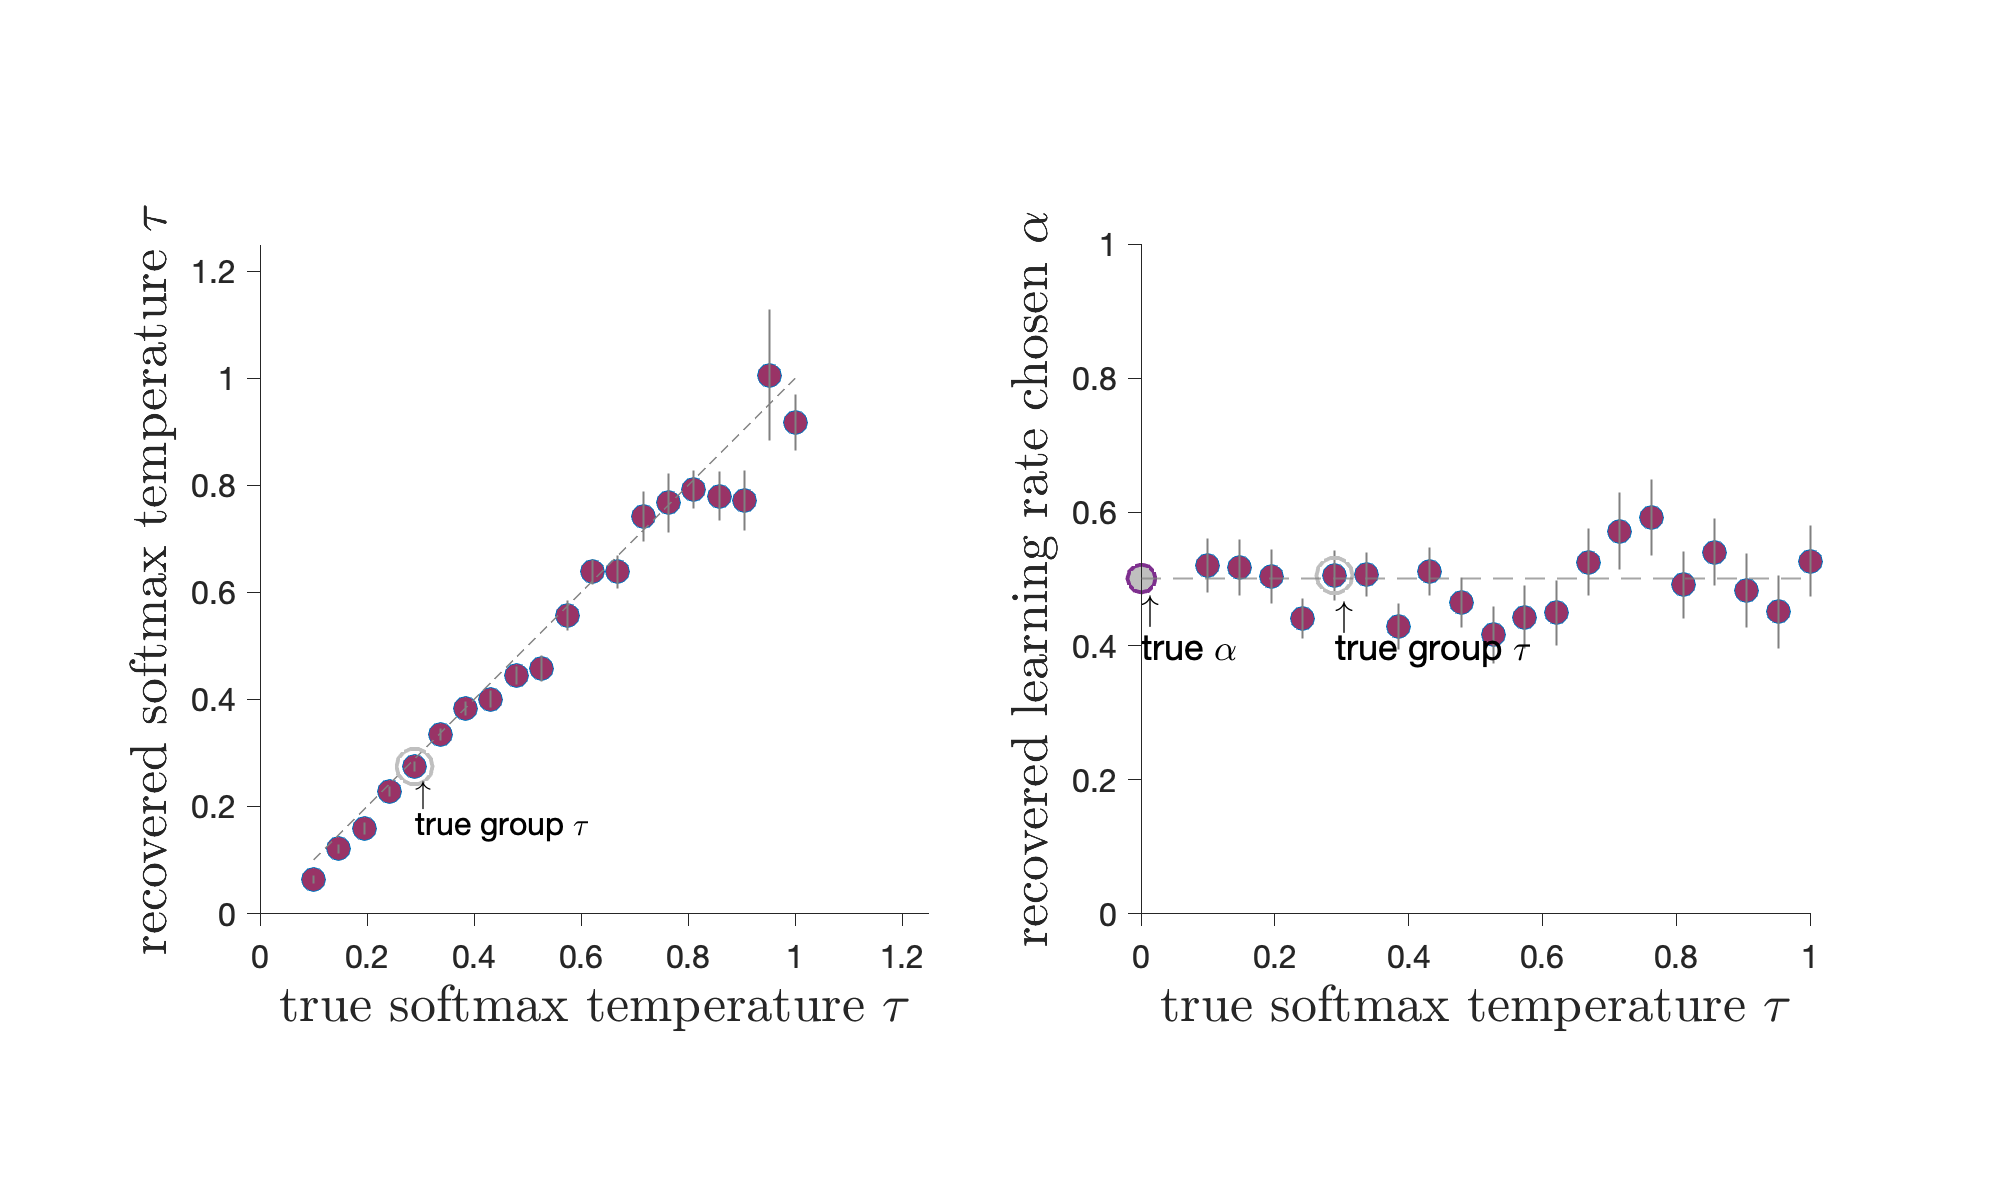

clc; 
close all; 

pbar = 1.0; 
figure('Color','white','Name',sprintf('Parameter recovery for %s',cfg_sim.paramname)); 
set(gcf, 'Position',  [100, 100, 1000, 600])
hold on
subplot(1,2,1); 

true          = sim_param; 
recovered     =  fitTable.tau; 
recovered_sem = fitTable.tau_sem; 

h1 = plot(true,recovered,'o','MarkerSize',12); hold on; 
h2 = errorbar(true,recovered,recovered_sem,'LineStyle','None','LineWidth',1.0); 
h3 = plot(true,true,'--','LineWidth',0.75); 


min_idx = find(abs((sim_param-0.3)) == min(abs(sim_param-0.3))); 
h4 = plot(true(min_idx),recovered(min_idx),'o','MarkerSize',18,'LineWidth',2);


set(h1(1),'MarkerFaceColor',[153,51,102]/255);
set(h2(1),'Color',[0.5,0.5,0.5]);
set(h3(1),'Color',[0.5,0.5,0.5]);
set(h4(1),'MarkerEdgeColor',[0.75,0.75,0.75]);


h2.CapSize = 0; 

text(true(min_idx),sim_param(min_idx)-0.06,'\uparrow','FontSize',16)
text(true(min_idx),sim_param(min_idx)-0.12,'true group \tau','FontSize',16)



xlim([0,max(true)+0.25]);
ylim([0,max(true)+0.25]);
% set(gca,'Layer','top','Box','off','PlotBoxAspectRatio',[pbar,1,1]);

set(gca,'Layer','top','Box','off'); 

set(gca,'TickDir','out','TickLength',[1,1]*0.02/max(pbar,1));
set(gca,'FontName','Helvetica','FontSize',16);
xlabel('true softmax temperature ${\tau}$','Interpreter','Latex','FontSize',26);
ylabel('recovered softmax temperature ${\tau}$','Interpreter','Latex','FontSize',26);
axis square


subplot(1,2,2); 

true          = sim_param; 
recovered     =  fitTable.alphach; 

recovered_sem = fitTable.alphach_sem; 

h1 = plot(true,recovered,'o','MarkerSize',12); hold on; 
h2 = errorbar(true,recovered,recovered_sem,'LineStyle','None','LineWidth',1.0); 
h3 = yline(cfg_sim.alphach,'--','LineWidth',1.0); 
h4 = plot(true(min_idx),recovered(min_idx),'o','MarkerSize',18,'LineWidth',2);
h5 = plot(0,cfg_sim.alphach,'o','MarkerSize',14,'LineWidth',2);

set(h3(1),'Color',[0.5,0.5,0.5]);
set(h1(1),'MarkerFaceColor',[153,51,102]/255);
set(h2(1),'Color',[0.5,0.5,0.5]);
set(h4(1),'MarkerEdgeColor',[0.75,0.75,0.75]);
set(h5(1),'MarkerFaceColor',[0.75,0.75,0.75]);

h2.CapSize = 0; 

text(true(min_idx),cfg_sim.alphach-0.05,'\uparrow','FontSize',18)
text(true(min_idx),cfg_sim.alphach-0.1,'true group \tau','FontSize',18)

% text(0,cfg_sim.alphach+0.06,'\downarrow true \alpha','FontSize',18)
text(0,cfg_sim.alphach-0.04,'\uparrow','FontSize',18)
text(0,cfg_sim.alphach-0.1,'true \alpha','FontSize',18)

xlim([0,max(true)]);
ylim([0,max(true)]);
% set(gca,'Layer','top','Box','off','PlotBoxAspectRatio',[pbar,1,1]);
set(gca,'Layer','top','Box','off');

set(gca,'TickDir','out','TickLength',[1,1]*0.02/max(pbar,1));
set(gca,'FontName','Helvetica','FontSize',16);
xlabel('true softmax temperature ${\tau}$','Interpreter','Latex','FontSize',26);
ylabel('recovered learning rate chosen ${\alpha}$','Interpreter','Latex','FontSize',26);
axis square


drawnow;

## === Additional functions ====== %%

function out = simulate_data(cfg)

if ~isfield(cfg,'p')
    fprintf('No reward probability specified, assume probability of reward is 0.75\n')
    p = 0.75;
else
    p = cfg.p;
end


if ~isfield(cfg,'tau')
    fprintf('No value for softmax, assuming tau = 0.1\n')
    tau = 0.1;
else
    tau  = cfg.tau;
end


if ~isfield(cfg,'alphach')
    fprintf('No value for learning rate chosen, assuming learnng rate chosen = 0.5\n')
    alphach = 0.5;
else
    alphach  = cfg.alphach;
end


if ~isfield(cfg,'alphauch')
    fprintf('No value for learning rate unchosen, assuming no update for the unchosen option\n')
    alphauch = 0;
else
    alphauch  = cfg.alphauch;
end

if ~isfield(cfg,'nsub')
    fprintf('Assuming 1 subject\n')
    nsub  = 1;
else
    nsub  = cfg.nsub;
end


if ~isfield(cfg,'ntrl')
    fprintf('Assuming 120 trials\n')
    
    ntrl  = 120;
else
    ntrl  = cfg.ntrl;
end


if ~isfield(cfg,'nblck')
    fprintf('Assuming 2 blocks\n')
    
    nblck  = 2;
else
    nblck  = cfg.nblck;
end


ntrl_blck = ntrl/nblck;



for i_s = 1:nsub
    
    fprintf('Simulating subject %d\n',i_s)
    % create binary rewards with reward probability p
    rew1 = [];
    rew2 = [];
    
    for i_b = 1:nblck
        
        r1                  = zeros(1,ntrl);
        r2                  = zeros(1,ntrl); 
        
        r1(1:floor(ntrl*p))     = 1; 
        r1(1:floor(ntrl*(1-p))) = 1; 
        
        r1 = r1(randperm(length(r1))); 
        r2 = r2(randperm(length(r2))); 
        
        if mod(i_b,2) == 1
            rew1 = cat(2,rew1,r1);
            rew2 = cat(2,rew2,r2);
            
        else
            rew1 = cat(2,rew1,r2);
            rew2 = cat(2,rew2,r1);
        end
    end
    
    rewards = cat(1,rew1,rew2);
    
    resp    = get_simulate(rewards,alphach,alphauch,tau); 
    
    out(i_s).resp    = resp; 
    out(i_s).rewards = rewards; 
    
    
%     figure; 
%     plot(out.rewards(1,:),'or'); hold on; plot(out.rewards(2,:),'ob')
%     plot(out.resp-1,'ok');
     
    
end
end

% simulate agent with specific learning paramaters 

function [resp] = get_simulate(rewards,alphach,alphauch,tau)

    % compute Q-values
    ntrl    = size(rewards,2); 
    q       = nan(ntrl,2);
    resp    = nan(ntrl,1); 
    
    q(1,:) = 0.5;
    vm     = [0.5,0.5]; % cached value for each bandit
    
    % first choice is random 
    resp(1) = double(rand>0.5)+1; % between 1 and 2 
    
    for itrl = 2:ntrl
        
        r = resp(itrl-1);
        
        
        vm(r)   = rewards(r,itrl-1); % update cached value for chosen bandit
        vm(3-r) = 1 - vm(r); % assume anticorrelation
        
        % update the Q-values
        q(itrl,r)   = q(itrl-1,r)+alphach*(vm(r)-q(itrl-1,r));
        q(itrl,3-r) = q(itrl-1,3-r)+alphauch*(vm(3-r)-q(itrl-1,3-r));
        
        
        deltaQ = q(itrl,1) - q(itrl,2);    % difference in Q values between options 1 and option 2 
        proba  = 1./(1+exp(-deltaQ/tau));  % softmax for 2 options 
        
        resp(itrl) = (1-sampleFromArbitraryP([proba,1-proba],[1,0]',1))+1; 
        
    end
   
end


function [out] = fit_mle(cfg)

resp     = cfg.resp;
% set response lookup indices
ntrl    = length(resp);
rewards = cfg.rewards; 

ipost = sub2ind([ntrl,2],(1:ntrl)',resp);

% define model parameters
npar = 0;
pnam = {}; % parameter name
psiz = []; % parameter size
pini = []; % parameter initialization value
pmin = []; % parameter minimum value
pmax = []; % parameter maximum value


% learning rate
npar = npar+1;
pnam{npar,1} = 'alphach';
psiz(npar,1) = 1;
pini(npar,1) = 0.5;
pmin(npar,1) = 0;
pmax(npar,1) = 1;

% learning rate unchosen
npar = npar+1;
pnam{npar,1} = 'alphauch';
psiz(npar,1) = 1;
pini(npar,1) = 0.5;
pmin(npar,1) = 0;
pmax(npar,1) = 1;


% softmax temperature
npar = npar+1;
pnam{npar,1} = 'tau';
psiz(npar,1) = 1;
pini(npar,1) = 0.5;
pmin(npar,1) = 0.001;
pmax(npar,1) = 100;


% define fixed parameters = parameters that are not fitted 
pfix = cell(npar,1);
for i = 1:npar
    if isfield(cfg,pnam{i})
        pfix{i} = reshape(cfg.(pnam{i}),[psiz(i),1]);
    end
end

% define free parameters to fit
ifit = cell(npar,1);
pfit_ini = [];
pfit_min = [];
pfit_max = [];
n = 1;


for i = 1:npar
    if isempty(pfix{i}) % free parameter
        ifit{i}  = n+[1:psiz(i)]-1;
        pfit_ini = cat(1,pfit_ini,pini(i)*ones(psiz(i),1));
        pfit_min = cat(1,pfit_min,pmin(i)*ones(psiz(i),1));
        pfit_max = cat(1,pfit_max,pmax(i)*ones(psiz(i),1));
        n = n+psiz(i);
    elseif numel(pfix{i}) ~= psiz(i)
        error('wrong size for fixed parameter %s!',pnam{i});
    elseif any(isnan(pfix{i})) % partly fixed parameter
        nfit = nnz(isnan(pfix{i}));
        ifit{i} = n+[1:nfit]-1;
        pfit_ini = cat(1,pfit_ini,pini(i)*ones(nfit,1));
        pfit_min = cat(1,pfit_min,pmin(i)*ones(nfit,1));
        pfit_max = cat(1,pfit_max,pmax(i)*ones(nfit,1));
        n = n+nfit;
    end
end
nfit = length(pfit_ini);

% fit free parameters
if nfit > 0
    pval = fmincon(@fmin,pfit_ini,[],[],[],[],pfit_min,pfit_max,[], ...
        optimset('Display','notify','FunValCheck','on','Algorithm','interior-point','TolX',1e-20,'MaxFunEvals',1e6)); 
    [~,phat] = fmin(pval);
else
    phat = pfix;
end

% get best-fitting parameters
out = cell2struct(phat,pnam);

% get quality of fit
out.nfit = nfit; % number of fitted parameters
out.ntrl = ntrl; % number of observations
out.llh  = get_llh(phat{:}); % model log-likelihood
out.aic  = -2*out.llh+2*nfit+2*nfit*(nfit+1)/(ntrl-nfit+1); % model AIC
out.bic  = -2*out.llh+nfit*log(ntrl); % model BIC

[out.ppost,out.q] = get_ppost(phat{:});

    function [f,pfit] = fmin(p)
    % create list of model parameters
    pfit = cell(npar,1);
    for i = 1:npar
        if isempty(pfix{i}) % free parameter
            pfit{i} = p(ifit{i});
        elseif any(isnan(pfix{i})) % partly fixed parameter
            pfit{i} = pfix{i};
            pfit{i}(isnan(pfit{i})) = p(ifit{i});
        else % fully fixed parameter
            pfit{i} = pfix{i};
        end
    end
    % return negative model log-likelihood
    f = -get_llh(pfit{:});
    end

    function [llh,ppost] = get_llh(varargin)
    % get model posterior probabilities
    ppost = get_ppost(varargin{:});
    ppost = [ppost,1-ppost];
    % get model log-likelihood
    
    
    llh = sum(log(max(ppost(ipost),eps)));
    end

    function [ppost,q] = get_ppost(alphach,alphauch,tau)
    
        q       = nan(ntrl,2);
        
        q(1,:) = 0.5;
        vm     = [0.5,0.5]; % cached value for each bandit
        
        
        for itrl = 2:ntrl
            
            r = resp(itrl-1);
            vm(r)   = rewards(r,itrl-1); % update cached value for chosen bandit
            vm(3-r) = 1 - vm(r); % assume anticorrelation
            
            % update the Q-values
            q(itrl,r)   = q(itrl-1,r)+alphach*(vm(r)-q(itrl-1,r));
            q(itrl,3-r) = q(itrl-1,3-r)+alphauch*(vm(3-r)-q(itrl-1,3-r));
            
        end
        
        ppost = 1./(1+exp(-(q(:,1)-q(:,2))/tau));
        ppost = eps*0.5+(1-eps)*ppost; % to prevent log(0) 
        
        
    end % end ggpost 

end